t = [0 .3 .8 1.1 1.6 2.3]'

t =          0
    0.3000
    0.8000
    1.1000
    1.6000
    2.3000


y = [0.82 .72 .64 .60 .55 .50]'

y =     0.8200
    0.7200
    0.6400
    0.6000
    0.5500
    0.5000


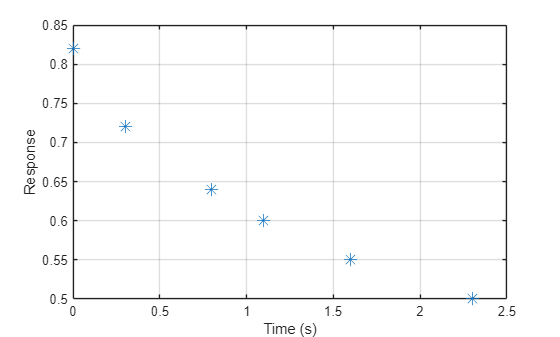

plot(t,y,'*','MarkerSize',10)
grid on
xlabel('Time (s)');
ylabel('Response');
hold on

E = [ones(size(t)) exp(-t)]

E =     1.0000    1.0000
    1.0000    0.7408
    1.0000    0.4493
    1.0000    0.3329
    1.0000    0.2019
    1.0000    0.1003


c = E\y

c =     0.4778
    0.3409


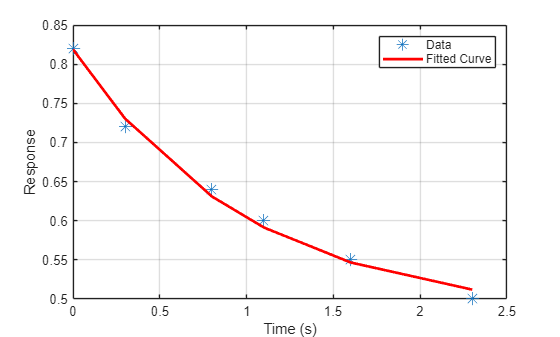

yFit = E * c; % Calculate the fitted values
plot(t, yFit, 'r-', 'LineWidth', 2); % Plot the fitted curve
legend('Data', 'Fitted Curve'); % Add a legend